n = 9

n = 1

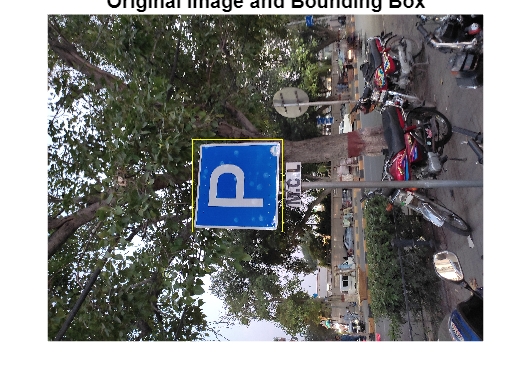

filenameImage = trainingData.imageFilename{n};
I = imread(filenameImage);
bbox = [trainingData.TrafficSign{n}];
label = "sign";
% display the image and bounding box.

annotatedImage = insertShape(I,"rectangle",bbox,"LineWidth",8);
imshow(annotatedImage)
title('Original Image and Bounding Box')

**Resize Image **

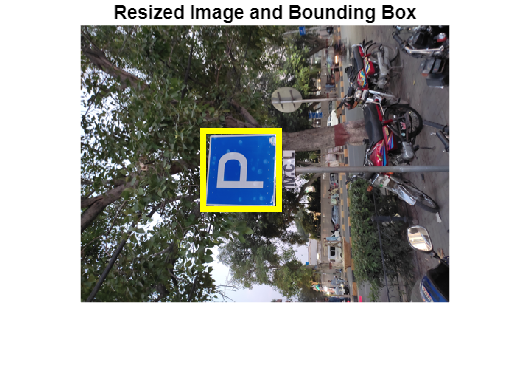

scale = 1/8;
J = imresize(I,scale);
bboxResized = bboxresize(bbox,scale);
annotatedImage = insertShape(J,"rectangle",bboxResized,"LineWidth",8);
imshow(annotatedImage)
title('Resized Image and Bounding Box')

**Random Rotation**

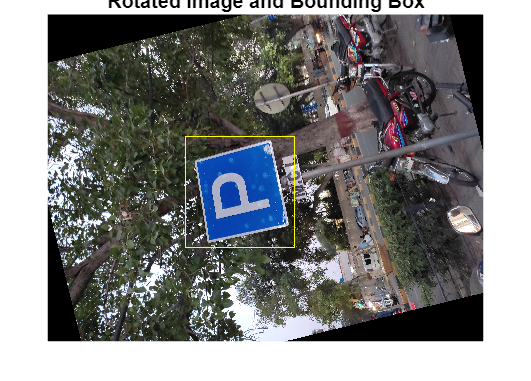

tform = randomAffine2d("Rotation",[-15 15]);
rout = affineOutputView(size(I),tform);
J = imwarp(I,tform,"OutputView",rout);
bboxRotated = bboxwarp(bbox,tform,rout,"OverlapThreshold",0.5);
annotatedImage = insertShape(J,"rectangle",bboxRotated,"LineWidth",8);
imshow(annotatedImage)
title('Rotated Image and Bounding Box')